S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000649.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000650.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000651.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000652.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000653.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000654.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000655.png'

S = 'E:\DDI\class\'

SS = 'E:\DDI\class\000656.png'

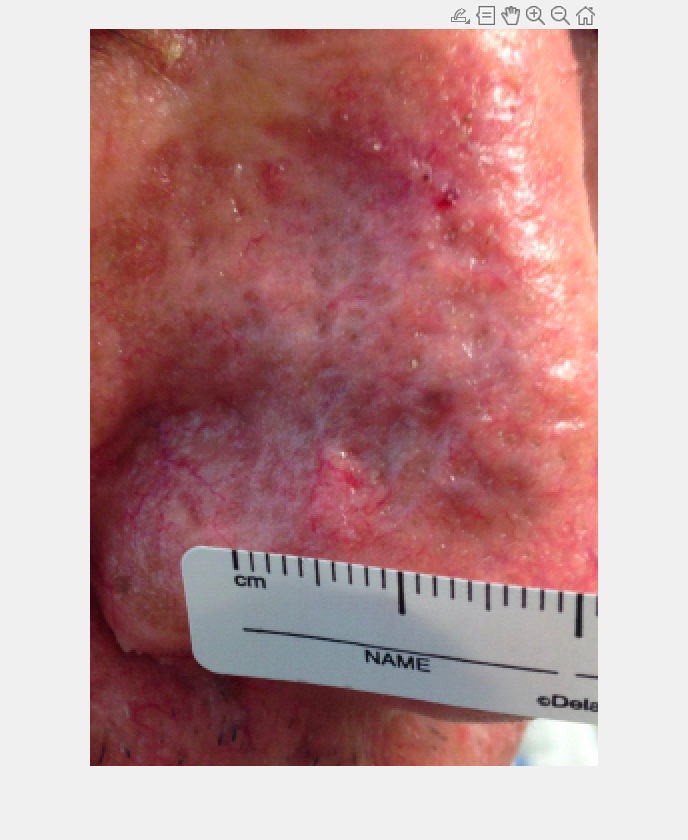

filePattern = fullfile('E:\DDI\class', '*.png');
filepath = 'E:\DDI\DDI_Cropped';
images = dir(filePattern) ;  % GEt all images of the folder 
N = length(images) ;     % number o fimages 
for i = 1:N
    S = strcat(images(i).folder, '\')
    SS = strcat(S, images(i).name) %Concatenating full image name so imread could read it
    I = imread(SS) ;   % REad image 
    I = imcrop(I) ;           % crop image 
    [filepath,name,ext] = fileparts(SS) ;

    imwrite(I,strcat('E:\DDI\DDI_Cropped\', strcat(name,ext))) ;   % Save image in the path 
end